# Zircaloy-2

data = readtable('Zr-2.xlsx');
data.Properties.VariableNames = {'Strain','Strain Rate','T1','T2','T3','T4','T5','T6','T7'}

data = 7×9 table
    Strain    Strain Rate     T1      T2      T3      T4      T5      T6      T7 
    ______    ___________    _____    ___    ____    ____    ____    ____    ____

     NaN           NaN         650    700     750     800     850     900     950
     0.5         0.001       112.9     80    63.5    36.7    21.3    11.2     3.9
     0.5          0.01       167.8    119      82    57.6    34.6    24.5    10.2
     0.5           0.1         219    185     115      85      56      31    17.5
     0.5             1         270    250     232     175     105      57      34
     0.5            10         261    250     249     240     152      90      54
     0.5           1

data(1,:)=[];

datan= table2array(data);
% 0.5 strain
strain_1 = datan(:,2:end);
sr1 = strain_1(:,1);
strainlog = log10(sr1);
stress1 = strain_1(:,2:end);
y = zeros(6,7);
stresslog = log10(stress1);
C = {'r','g','m','b','k','c',[0.6350 0.0780 0.1840]};
hold on
for r = 1:7
    Scatter(r) =scatter(strainlog,stresslog(:,r),'filled','MarkerFaceColor',C{r});
    c= polyfit(log10(sr1),log10(stress1(:,r)),1);
    y(:,r) = polyval(c,log10(sr1));
    plot(log10(sr1),y(:,r),'LineWidth',1.5,'Color',C{r})
end
ylabel('Flow Stress');xlabel('Strain Rate');
title('Flow Stress v/s Strain Rate')
legend(Scatter,'650°C','700°C','750°C','800°C','850°C','900°C','950°C','Location','southeast','FontSize',10);

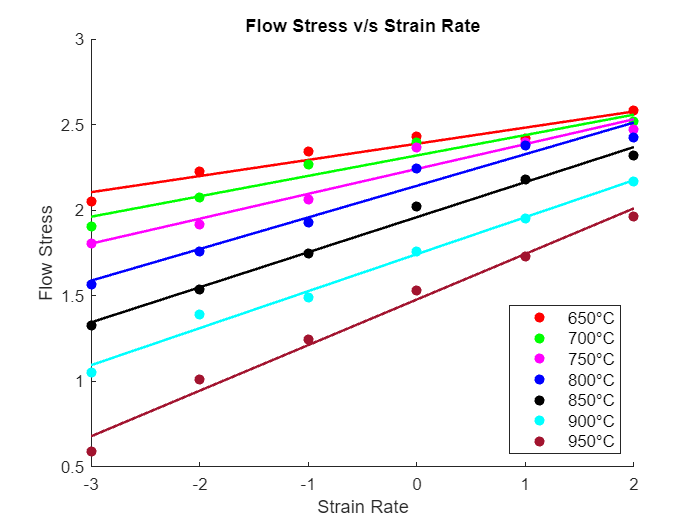

hold off

%slope or strain rate sensitivity
%slope or strain rate sensitivity
m= zeros(6,7);
for k =  1:7
 for p = 1:6 
        c1= polyfit(log10(sr1),log10(stress1(:,k)),3);
        deriv = polyder(c1);
        m(p,k) = polyval(deriv,strainlog(p));
 end
end


e= (2*m./(m+1))*100;
T= 650:50:950;
%instability zone
e1= e/200;
slope= zeros(6,7);
for k =  1:7
    for p =  1:6
        c2= polyfit(log10(sr1),log10(e1(:,k)),3);
        deriv = polyder(c2);
        slope(p,k) = polyval(deriv,strainlog(p));
       
    end
end
iz = slope +m;

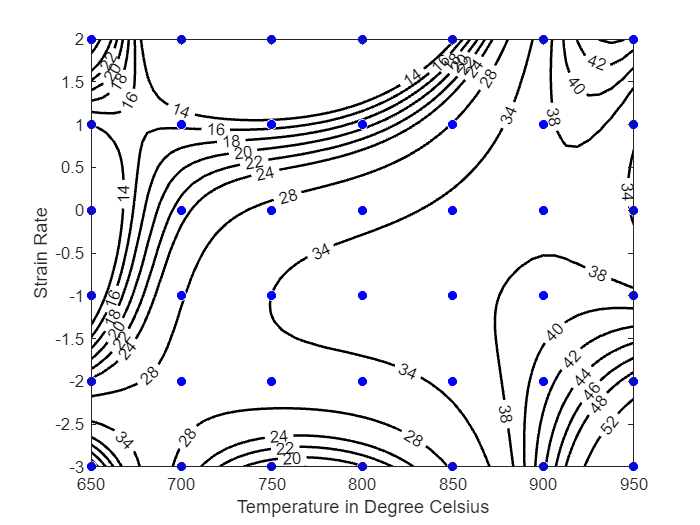

%% Fit: 'untitled fit 1'.
[xData, yData, zData] = prepareSurfaceData( T, strainlog, e );

% Set up fittype and options.
ft = fittype( 'poly45' );

% Fit model to data.
[fitresult] = fit( [xData, yData], zData, ft, 'Normalize', 'on' );

% Make contour plot.
figure( 'Name', 'Power Dissipation' );
h = plot( fitresult, [xData, yData], zData, 'Style', 'Contour' );
% Label axes
xlabel( 'Temperature in Degree Celsius', 'Interpreter', 'none' );
ylabel( 'Strain Rate', 'Interpreter', 'none' );

grid off
set(h(1),'ShowText','on','LabelSpacing',144)
set(h(1),'LineWidth',1.5,'Fill','off');
set(h(1),'LevelList',[14,16,18,20,22,24,28,34,38,40,42,44,46,48,52])
fig = gcf;
saveas(gcf,'pdZr-2.jpg')


%% Fit: 'untitled fit 2'.
[xData, yData, zData] = prepareSurfaceData( T, strainlog, iz );

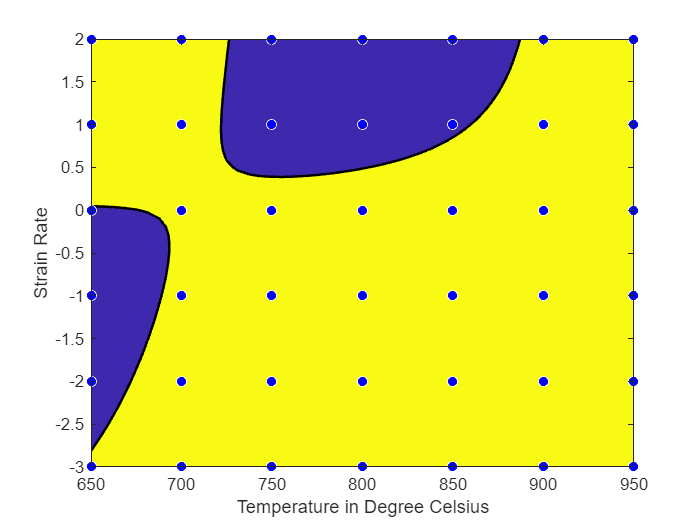


% Set up fittype and options.
ft = fittype( 'poly24' );

% Fit model to data.
[fitresult] = fit( [xData, yData], zData, ft, 'Normalize', 'on' );

% Make contour plot.
figure( 'Name', 'untitled fit 2' );
w=plot( fitresult, [xData, yData], zData, 'Style', 'Contour' );
% Label axes
xlabel( 'Temperature in Degree Celsius', 'Interpreter', 'none' );
ylabel( 'Strain Rate', 'Interpreter', 'none' );
grid off
set(w(1),'LineWidth',1.5,'LevelStep',1);
fig = gcf;
saveas(gcf,'isZr-2.jpg')

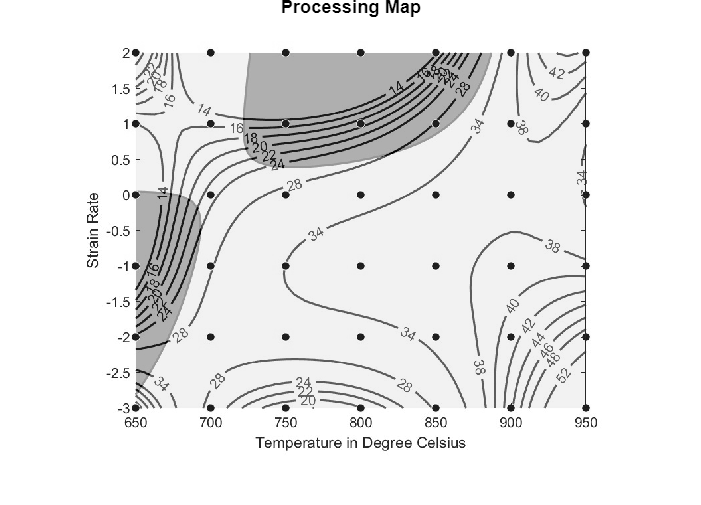

% BASIC IMAGE PROCESSING : SUPERIMPOSE
fig1 = imread('pdZr-2.jpg');
fig2 = imread('isZr-2.jpg');
fusionimage=imfuse(fig1,fig2,'falsecolor','Scaling','joint');
op=rgb2gray(fusionimage);
imshow(op);
title('Processing Map')